% Message = textread('D:\Bristol\23-24\Project\Hardware\Simpler\Tx1\header.txt', '%d', 'delimiter', ' ')
% my_QAM = qammod(MessageLength,4,"InputType","bit","UnitAveragePower",true)
numcarr = 1024;

GB_len = numCarr/16;
left_gb = 1:GB_len

left_gb =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


right_gb = (numCarr-GB_len+1):numCarr

right_gb =          961         962         963         964         965         966         967         968         969         970         971         972         973         974         975         976         977         978         979         980         981         982         983         984         985         986         987         988         989         990         991         992         993         994         995         996         997         998         999        1000        1001        1002        1003        1004        1005        1006        1007        1008        1009        1010


if mod(numCarr,2) == 0
    mid_guard = (numCarr/2)+1
else
    mid_guard = (numCarr+1)/2
end

mid_guard = 513


nullIdx = [left_gb, mid_guard, right_gb]'

nullIdx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


my_test_head = zeros(numcarr-length(nullIdx),1) 

my_test_head =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% barker =  [+1, +1, +1, +1, +1, -1, -1, +1, +1, -1, +1, -1, +1]';
% my_test_head(1:length(barker)) = barker

my_test_head(55) = 1

my_test_head =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



cycpre = numcarr/16;
my_ofdm = ofdmmod(my_test_head,numcarr,numcarr/16,nullIdx)

my_ofdm = 	1.0e+-3 *

  -0.6905 - 0.6905i
   0.0599 + 0.9747i
   0.6008 - 0.7699i
  -0.9601 + 0.1787i
   0.8376 + 0.5021i
  -0.2949 - 0.9310i
  -0.3957 + 0.8928i
   0.8879 - 0.4067i
  -0.9345 - 0.2835i
   0.5123 + 0.8314i


my_real_tx_gain = 1 / max(real(my_ofdm))

my_real_tx_gain = 1024

my_imag_tx_gain = 1 / max(imag(my_ofdm))

my_imag_tx_gain = 1024

my_tx_gain = min(my_real_tx_gain,my_imag_tx_gain)

my_tx_gain = 1024


my_ofdm = my_ofdm.*my_tx_gain

my_ofdm =   -0.7071 - 0.7071i
   0.0613 + 0.9981i
   0.6152 - 0.7883i
  -0.9831 + 0.1830i
   0.8577 + 0.5141i
  -0.3020 - 0.9533i
  -0.4052 + 0.9142i
   0.9092 - 0.4164i
  -0.9569 - 0.2903i
   0.5246 + 0.8514i


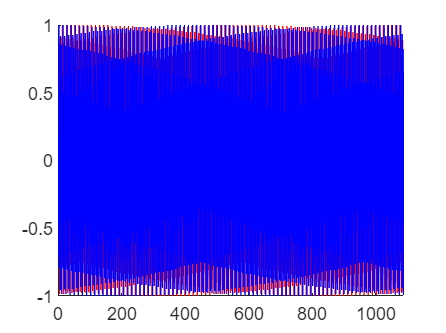


save('D:\Bristol\23-24\Individual Project\20240410_2\Tx2\4QAM\complexArray.mat', 'my_ofdm');

hold on
plot(real(my_ofdm),'r')
plot(imag(my_ofdm),'b')
hold off


temp = load('D:\Bristol\23-24\Individual Project\20240410_2\Tx2\4QAM\complexArray.mat',"my_ofdm")

temp = 包含以下字段的 struct :
    my_ofdm: [1088×1 double]


read_header = temp.my_ofdm

read_header =   -0.7071 - 0.7071i
   0.0613 + 0.9981i
   0.6152 - 0.7883i
  -0.9831 + 0.1830i
   0.8577 + 0.5141i
  -0.3020 - 0.9533i
  -0.4052 + 0.9142i
   0.9092 - 0.4164i
  -0.9569 - 0.2903i
   0.5246 + 0.8514i
